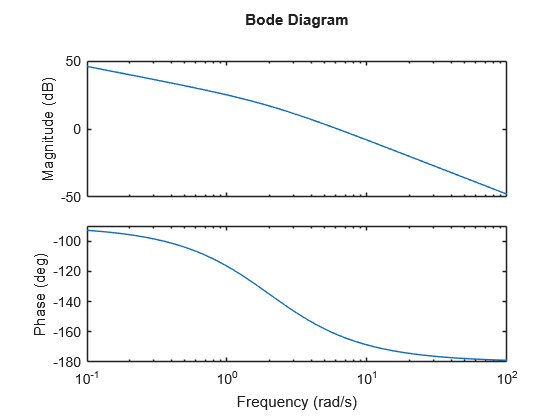

% Constante de erro estatico de velocidade kv de 20s^-1 -> kv = 2*K
% K = kv/2 = 10

% Margem de fase de ao menos 50°
% Margem de ganho de, no minimo, 10db

s = tf('s');
K = 10;
G = 4/(s*(s+2));
Gl = K*G;
bode(Gl)


% Passo 3: Margem de fase requerida - margem de fase encontrada + margem adicional
% 50 - 18 + 8 = 40°
% Encontrar alfa: (1 - sen(40))/(1 + sen (40))
a = (1 - sind(40))/(1 + sind(40))

a = 0.2174


% Encontrar a frequencia de ponto medio
% Wm = -20log(1/sqrt(a)) *na base 10, em db
WmMag = -20*log10(1/sqrt(a))

WmMag = -6.6265

Wm = 9.15

Wm = 9.1500


% Para Wm = -6.6265, buscar no grafico de magnitude a nova frequencia de ponto medio, Wm = 9.15 rad/s
T = 1/(Wm*sqrt(a))

T = 0.2344


Gc = K*(T*s+1)/(a*T*s + 1)


Gc =
 
  2.344 s + 10
  -------------
  0.05096 s + 1
 
Continuous-time transfer function.


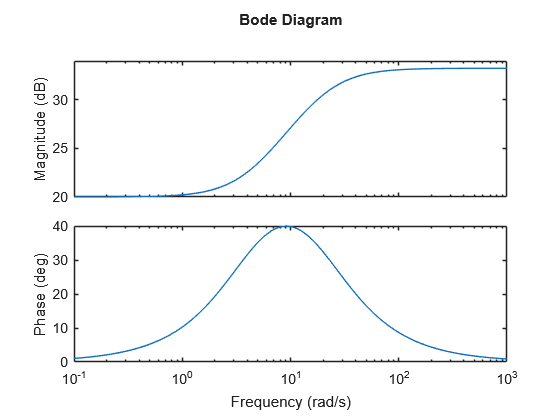

bode(Gc)

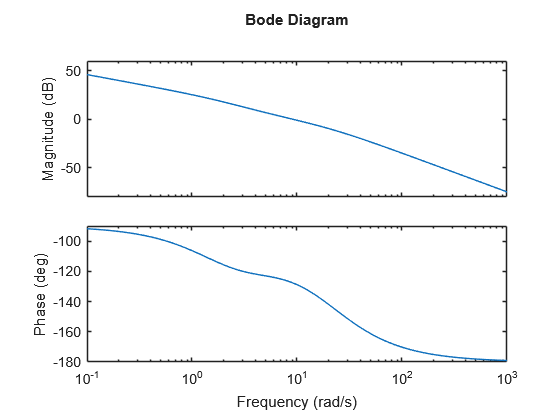

bode(Gc*G)


% A nova fase calculada (40°) corresponde a nova frequencia de cruzamento de de ganho

step(feedback(G,1))
hold

Current plot held


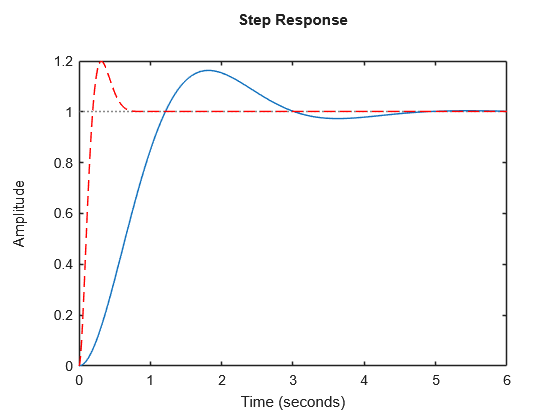

step(feedback(Gc*G,1),'--red')